clear all
clc
close all

## DEFINING VARIABLES %%

Crisp Inputs

- Current position (*x_boat*)

- Current velocity (*v_boat*)

Control Variable

- Port engine thrust (*T_port*)

- Starboard engine thrust (*T_stbd*)

Linguistic Variables/Values

- Velocity: Rapidly Decrease Speed(LP) / Decrease Speed(P)/ Continue at Current Speed(Z) / Increase Speed(N)/ Rapidly Increase Speed(LN)

- Position: Large Negative (LN) / Negative (N)/ Zero(Z))/ Positive(P)/ Large Positive(LP)

IRM

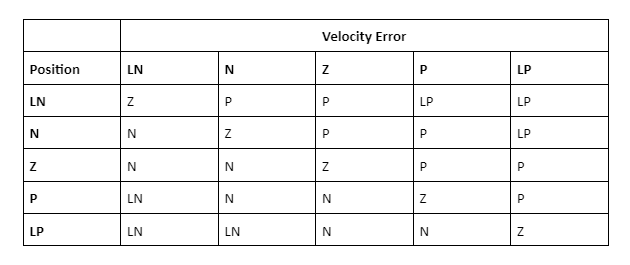

**Defining the Problem**

The desired distance is 10 meters starting at the point of origin of 0 meters following a linear path.

IRM With Crisp Values

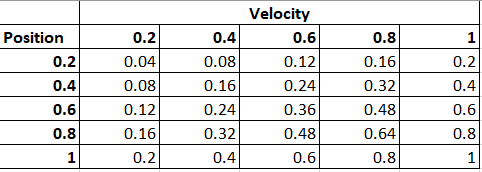

## Initialization

sp = [0,0]; % Starting point %
ep = [0,10]; % End Point %

% Crisp Values for Position and Velocity Error
LN = 0.2;
N = 0.4;
Z = 0.6;
P = 0.8;
LP = 1.0;

X = [LN;N;Z;P;LP]; % Position %
V = [LN N Z P LP]; % Velocity Error %

IRM = X.*V; % Inferenece Rule Matrix %
disp(IRM);

    0.0400    0.0800    0.1200    0.1600    0.2000
    0.0800    0.1600    0.2400    0.3200    0.4000
    0.1200    0.2400    0.3600    0.4800    0.6000
    0.1600    0.3200    0.4800    0.6400    0.8000
    0.2000    0.4000    0.6000    0.8000    1.0000



A = IRM(5,4); % Recall specific matrix element (Row, Col) %

t = 0:0.1:1; %s
% d = xo*t + A*(t^2)/2 % Distance traveled %

% Creating IRM using if/else %
X = [LN;N;Z;P;LP]; % Position %
n = length(X);
for i = 1:1:n;
    x(i) = X(i);
end

V = [LN N Z P LP]; % Velocity Error %
n = length(V);

for j = 1:1:n;
    v(j) = V(j);
end


% Setting up IRM with Loop % 
n = length(X);
m = length(V);
for i = 1:1:n;
    j = 1:1:m;
A(i,j) = x(i).*v(j)
end


**Loop Practice **

for i = 0.2:0.2:1
    x = i
end
for k = 0.2:0.2:1
    v = k
end

xo = 0
for j = 1
    xo = v*t
end

% d = xo*t + A*(t^2)/2 % Distance traveled %


% x = 0:0.2:10
% v = 0:0.2:10
% if 
%     x = 0.2
%     v = 0.2
% else a = x*v
% p = xo + xo*t + a*(t^2)/2

% path = x + x*v;


**Problem Statement**

If position is at [0:0.2:10] and velocity is at [0:0.2:10] then total acceleration is $A_{T\;} =T_{\mathrm{Port}} *\frac{t^2 }{2}+T_{\mathrm{Stbd}} *\frac{t^2 }{2}$ , but in this case because we are going straight, T_port and T_stbd are equal so $A_T =T*t^2$